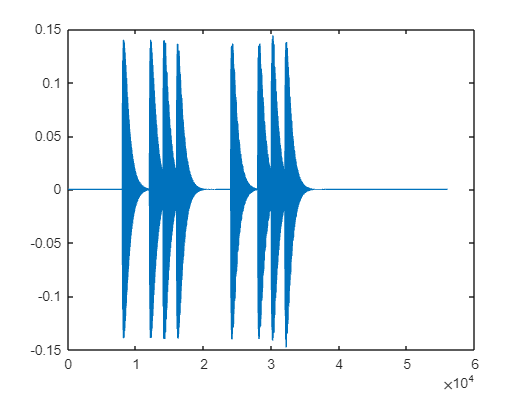

clear
clc

freqs = readmatrix("freqs.xlsx")';%读取频率
load("Guitar.MAT");
srate = 8000; %采样率
xfadet = 0.120; %渐变用时
[num, mag, basefreq, harmon] = toneanalyse(wave2proc,srate,freqs,10);

%music
musicdat = [0.5 0.25 0.25 0.5 0.5 0.5 0.25 0.25 0.5 0.5; 20 20 22 15 0 13 13 10 15 0; 0.7 0.7 0.7 0.7 0.7 0.7 0.7 0.7 0.7 0.7]';%音乐数据矩阵[持续时间,音符,幅度]
harmonrepeat = repmat(harmon,length(musicdat(:,1)),1);
musicdat = [musicdat,harmonrepeat];
music = musicgen(freqs,musicdat,srate,xfadet,0.75); %最后一个参数调为正值(0~2)可使每个音的延音等长，否则迭接固定为xfade长度

%sound
sound(music,8000);
plot(music);

仍然不是很像